依赖[统一实验分析作图v18.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

根据PCA取模板细胞

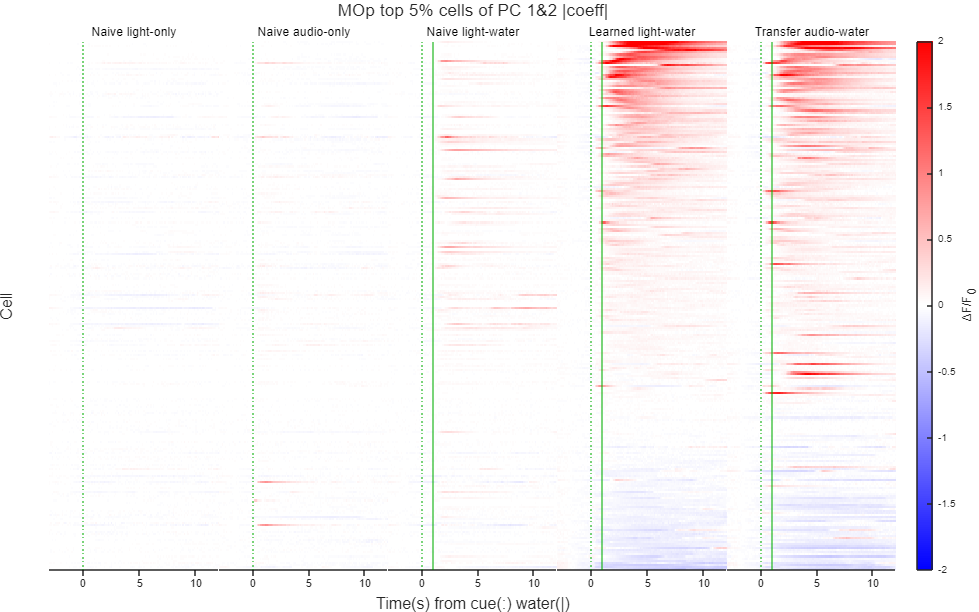

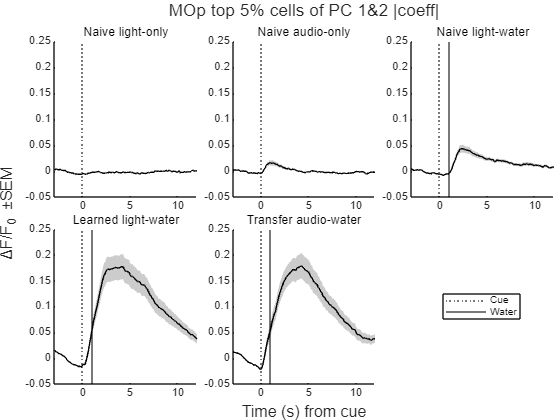

Impl(TransferLearning.Flags.LightAudio|TransferLearning.Flags.PPT);

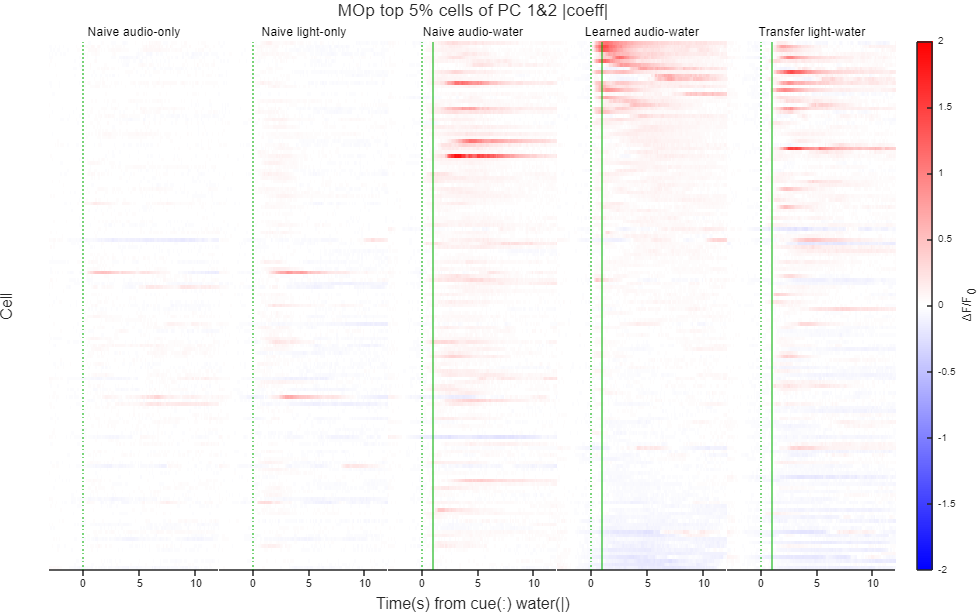

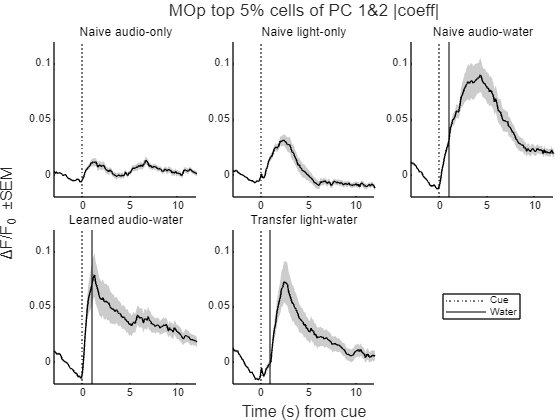

Impl(TransferLearning.Flags.AudioLight|TransferLearning.Flags.PPT);

function Impl(FigureFlag)
import TransferLearning.*
switch FigureFlag&Flags.Paradigm
	case Flags.LightAudio
		SheetName='迁移PC光声Top5';
		Paradigm='光声';
		SubTitles=["Naive light-only","Naive audio-only","Naive light-water","Learned light-water","Transfer audio-water"];
	case Flags.AudioLight
		SheetName='迁移PC声光Top5';
		Paradigm='声光';
		SubTitles=["Naive audio-only","Naive light-only","Naive audio-water","Learned audio-water","Transfer light-water"];
	otherwise
		Exception.Unsupported_paradigm.Throw;
end
HeatCalcium=NtatsFromSheetname(SheetName);
Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
HeatCalcium=2.^UniExp.HeatmapSort(HeatCalcium(ismember(HeatCalcium.CellUID,TemplateCellUID(0.05,1:2,Paradigm)),:),"Learned").NTATS{:,:,["Naive_cue_A","Naive_cue_B","Naive","Learned","Transfer"]}-1;
[Layout,Axes]=BasicHeatmap(HeatCalcium,SubTitles,Colors,false,WaterLine=false,CLim=[-2,2]);
for A=3:5
	xline(Axes(A),1,'-',Color=Colors(3,:));
end
title(Layout,'MOp top 5% cells of PC 1&2 |coeff|');
Target=Flags(FigureFlag&Flags.Target);
switch Target
	case Flags.Article
		MATLAB.Graphics.FigureAspectRatio(3,1,1);
	case Flags.PPT
		MATLAB.Graphics.FigureAspectRatio(8,5,2);
	otherwise
		Exception.Unsupported_target.Throw;
end
print(ProjectPath(sprintf('%s.热图.%s.svg',SheetName,Target)),'-dsvg');
[Mean,Sem]=MATLAB.DataFun.MeanSem(HeatCalcium,1);
Xs=linspace(-3,12,size(Mean,2))';
figure;
Layout=tiledlayout(2,3,TileSpacing='tight',Padding='tight');
Axes=gobjects(5,1);
for A=1:5
	Axes(A)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(Mean(:,:,A)',Sem(:,:,A)',X=Xs);
	CueLine=xline(0,':k');
	if A>2
		WaterLine=xline(1,'-k');
	end
	title(SubTitles(A));
end
L=legend([CueLine,WaterLine],["Cue","Water"]);
L.Layout.Tile=6;
MATLAB.UnifyYLims(Axes);
title(Layout,'MOp top 5% cells of PC 1&2 |coeff|');
ylabel(Layout,'ΔF/F_0 ±SEM');
xlabel(Layout,'Time (s) from cue');
print(ProjectPath(sprintf('%s.线图.%s.svg',SheetName,Target)),'-dsvg');
end